## Modello del 3°ordine con due zeri complessi e coniugati

syms s k w_nz w_np w_h xi_p xi_z w_Rp M_Rp w_Rz M_Rz

frf_joint1 = k*(s^2+2*xi_z*w_nz*s+w_nz^2)/((s+w_h)*(s^2+2*xi_p*w_np*s+w_np^2))

$$frf\_joint1 = \frac{k\,\left(s^{2}+2\,\xi_{z}\,s\,w_{\mathrm{nz}}+{w_{\mathrm{nz}}}^{2}\right)}{\left(s+w_{h}\right)\,\left(s^{2}+2\,\xi_{p}\,s\,w_{\mathrm{np}}+{w_{\mathrm{np}}}^{2}\right)}$$


w_Rp = w_np*sqrt(1-2*xi_p^2)

$$w\_Rp = w_{\mathrm{np}}\,\sqrt{1-2\,{\xi_{p}}^{2}}$$

w_Rz = w_nz*sqrt(1-2*xi_z^2)

$$w\_Rz = w_{\mathrm{nz}}\,\sqrt{1-2\,{\xi_{z}}^{2}}$$


M_Rp = 1/(2*xi_p*sqrt(1-xi_p^2))

$$M\_Rp = \frac{1}{2\,\xi_{p}\,\sqrt{1-{\xi_{p}}^{2}}}$$

M_Rz = 1/(2*xi_z*sqrt(1-xi_z^2))

$$M\_Rz = \frac{1}{2\,\xi_{z}\,\sqrt{1-{\xi_{z}}^{2}}}$$

Valori letti da grafico e convertiti dalla scala logaritmica

dc_gain = db2mag(-32)

dc_gain = 0.0251

M_Rp_val = db2mag(-42-(-50))

M_Rp_val = 2.5119

M_Rz_val = db2mag(-55-(-65))

M_Rz_val = 3.1623

w_h_val = 4

w_h_val = 4

w_Rp_val = 250

w_Rp_val = 250

w_Rz_val = 80

w_Rz_val = 80

Calcolo di w_nz w_np w_h xi_p xi_z

S_p = solve([M_Rp == M_Rp_val, w_Rp == w_Rp_val],[w_np xi_p]);
w_np_val = real(double(S_p.w_np(1)))

w_np_val = 261.0208

xi_p_val = double(S_p.xi_p(1))

xi_p_val = 0.2033


S_z = solve([M_Rz == M_Rz_val, w_Rz == w_Rz_val],[w_nz xi_z]);
w_nz_val = real(double(S_z.w_nz(1)))

w_nz_val = 82.1352

xi_z_val = double(S_z.xi_z(1))

xi_z_val = 0.1602

Calcolo di k

k_val = dc_gain*w_h_val*w_np_val^2/w_nz_val^2

k_val = 1.0147

Sostituzione valori calcolati

frf_joint1_val = subs(frf_joint1,{'k','w_h','w_nz','w_np','xi_z','xi_p'}, ...
                      {k_val,w_h_val,w_nz_val,w_np_val,xi_z_val,xi_p_val});

$$frf\_joint1\_val = \frac{2284973943458419\,\left(s^{2}+\frac{33355948330001188840214293907649\,s}{1267650600228229401496703205376}+\frac{33405526450006391703978396243009}{4951760157141521099596496896}\right)}{2251799813685248\,\left(s+4\right)\,\left(s^{2}+\frac{33634132460089695038813315376465\,s}{316912650057057350374175801344}+\frac{21085787211292858642985498073361}{309485009821345068724781056}\right)}$$

Calcolo funzione di trasferimento fattorizzata

[num,den] = numden(frf_joint1_val);
num = sym2poly(num);
den = sym2poly(den);
tf_joint1 = minreal(tf(num,den));
tf_zpk_joint1 = zpk(tf_joint1)

tf_zpk_joint1 =
 
   1.0147 (s^2 + 26.31s + 6746)
  -------------------------------
  (s+4) (s^2 + 106.1s + 6.813e04)
 
Continuous-time zero/pole/gain model.



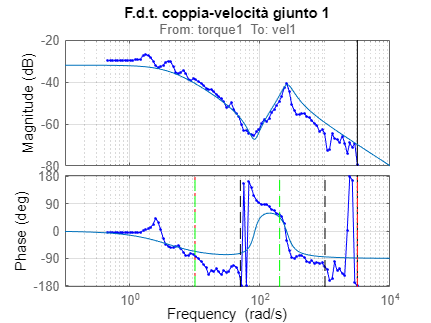


% bode(tf_zpk_joint1)


figure
bode(freq_resp_ident_joint1,'.-',bode_opts)
grid on
hold on
bode(tf_zpk_joint1)
plot(w0_chirp*[1 1],ylim,'-.r'); plot(w1_chirp*[1 1],ylim,'-.r')
plot(w0b_chirp*[1 1],ylim,'--g'); plot(w1b_chirp*[1 1],ylim,'--g')
plot(w0c_chirp*[1 1],ylim,'--k'); plot(w1c_chirp*[1 1],ylim,'--k')
hold off
title('F.d.t. coppia-velocità giunto 1')

## Modello del 5°ordine con due zeri complessi e coniugati